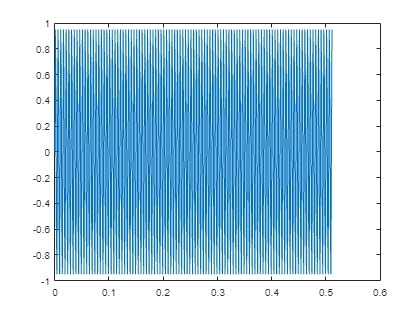

% generating individual sine waves
N    = 512;             % Length of signal
Fs   = 1000;            % Sampling frequency                    
T    = 1/Fs;            % Sampling period       
t    = (0:N-1)*T;       % Time vector

x200 = sin(2*pi*200*t); % x = sin(2*pi*f*t)
x400 = sin(2*pi*400*t);
x900 = sin(2*pi*900*t);

figure, plot(t,x200);

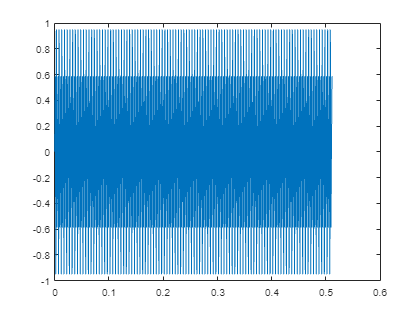

figure, plot(t,x400);

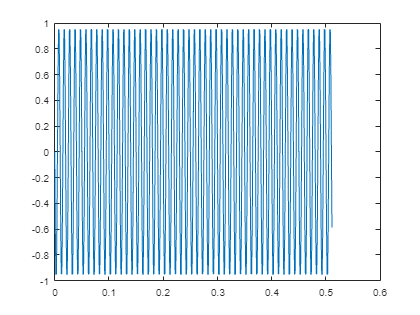

figure, plot(t,x900);

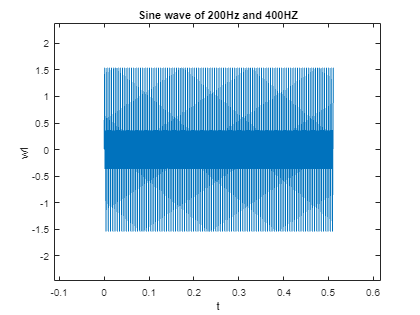


% generating waveforms
w1 = x200+x400;
w2 = x200+x900;

figure, plot(t,w1);
title("Sine wave of 200Hz and 400HZ")
xlabel("t"), ylabel("w1"),

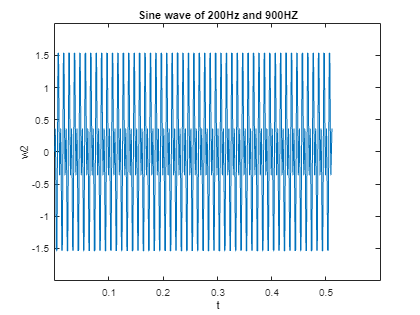

figure, plot(t,w2);
title("Sine wave of 200Hz and 900HZ")
xlabel("t"), ylabel("w2"),

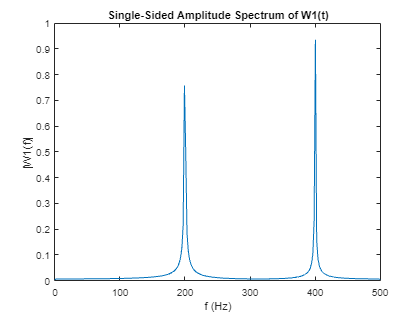


% taking fourier transform (and computing
% the one-sided amplitude spectrum)

W1 = fft(w1); % not aliased waveform

W1_P2 = abs(W1/N);
W1_P1 = W1_P2(1:N/2+1);
W1_P1(2:end-1) = 2*W1_P1(2:end-1);

% define the frequency domain f 
% and plot the single-sided amplitude spectrum 
f = Fs*(0:(N/2))/N;
figure, plot(f,W1_P1), 
title("Single-Sided Amplitude Spectrum of W1(t)")
xlabel("f (Hz)"), ylabel("|W1(f)|"),

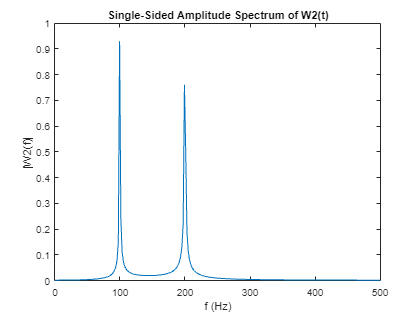



W2 = fft(w2); % aliased waveform

W2_P2 = abs(W2/N);
W2_P1 = W2_P2(1:N/2+1);
W2_P1(2:end-1) = 2*W2_P1(2:end-1);

% define the frequency domain f 
% and plot the single-sided amplitude spectrum 
f = Fs*(0:(N/2))/N;
figure, plot(f,W2_P1), 
title("Single-Sided Amplitude Spectrum of W2(t)")
xlabel("f (Hz)"), ylabel("|W2(f)|"),

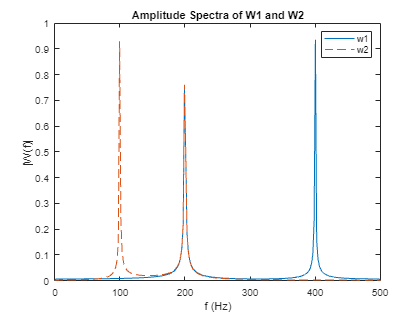


% super-imposed final answer
figure, plot(f,W1_P1, f,W2_P1, "--"), 
title("Amplitude Spectra of W1 and W2")
xlabel("f (Hz)"), ylabel("|W(f)|"),
legend('w1','w2');

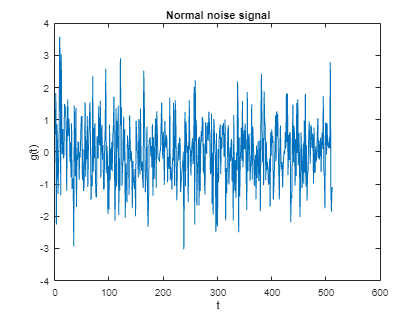

rng(0);     % constant random
N    = 512; % Length of signal

% generating gaussian noise signal
Fs   = 200;             % Sampling frequency                    
T    = 1/Fs;            % Sampling period       
t    = (0:N-1)*T;       % Time vector
g    = randn(1, N);     % Gaussian noise array

figure, plot(g),
title("Normal noise signal"),
xlabel("t"), ylabel("g(t)"),

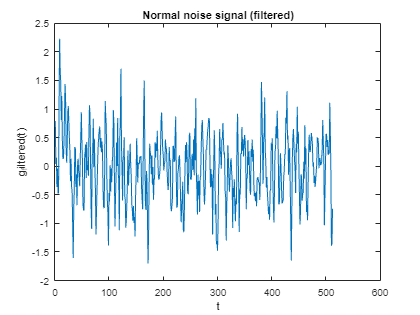


g_filtered = conv(g, [1/3 1/3 1/3], 'same');
% 'same' else resultant will be size+2
figure, plot(g_filtered),
title("Normal noise signal (filtered)"),
xlabel("t"), ylabel("g_filtered(t)");

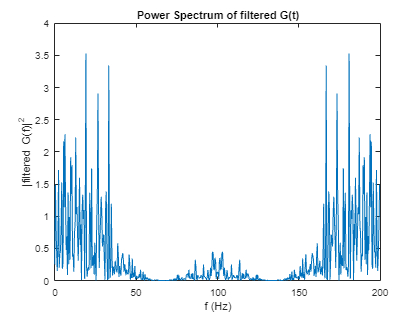


G_filtered = fft(g_filtered);

PS = (abs(G_filtered).^2)/N;

f = Fs*(0:(N-1))/N;
figure, plot(f,PS), 
title("Power Spectrum of filtered G(t)")
xlabel("f (Hz)"), ylabel("|filtered G(f)|^2");

% note the moving average filter act as a low pass filter